clear 
G=2.1686;   
R=48.9120; 
c=114.2959;

A=-1/(R*c);
B=[1/(R),G];
C=1/c;
D=[0,0];

Ta=22;
x0=Ta;
th=-22;
th2=-20;



stopTime=2*60*60;
fs=1;
dt=1/fs;
t=0:dt:stopTime;
Ta=22*ones(1,fs*stopTime+1);
Tas=timeseries(Ta,t);
out=sim('modelControl');


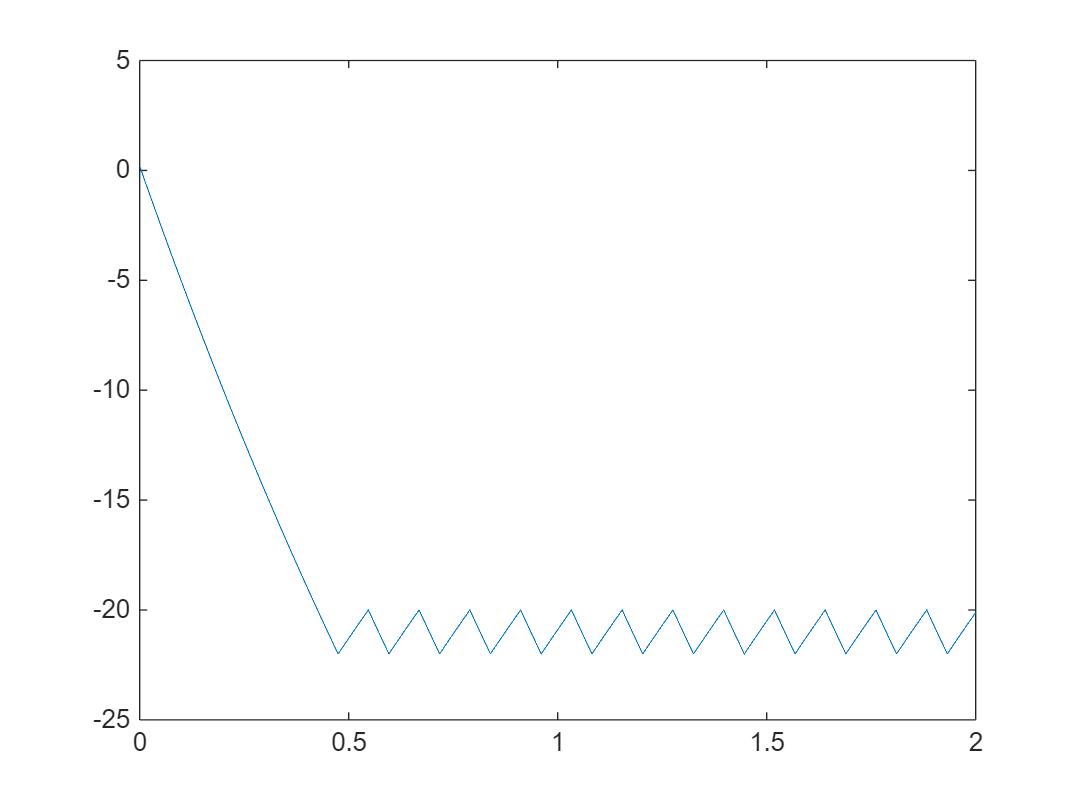

plot(t/(60*60),out.Y.Data)

clear 
G=2.1686;   
R=48.9120; 
c=114.2959;


Ta=22;
x0=Ta;
th=-22;
th2=-20;



stopTime=2*60*60;
fs=1;
dt=1/fs;
t=0:dt:stopTime;
Ta=22*ones(1,fs*stopTime+1);


[stopTime,dt,fs,Tas,A,B,C,D] = RealTimeSim(Ta,G,R,c,t,x0);
out=sim('modelControl');
Y=out.Y.Data;
plot(t/(60*60),Y)